**Robot movement in lidar scanned map using heuristics rolling window. Simply select an appropriate starting location.**

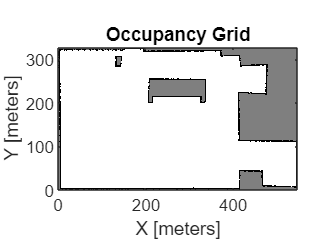


clear 
clc 

map = occupancyMap(readmatrix("map builder.xlsx", "Sheet","100 park"));
%mat = occupancyMatrix(map); %an array containing the actual values of each grid in the occupancy map
show(map)


n = zeros(map.GridSize(1), map.GridSize(2)); %generate array to store neural activity values

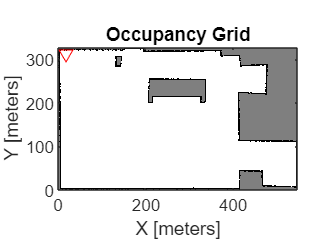

%initialize starting location
up_dir = '^r'; %indicator for robot heading direction on map
down_dir = 'vr'; %indicator for robot heading direction on map
left_dir = '<r'; 
right_dir = '>r';
hold on
pc = [15,18]; %starting grid location
xy = grid2world(map,[pc(1),pc(2)]); %convert starting grid location to xy coordinates
plot(xy(1), xy(2), down_dir) %plot starting location xy coordinates on map

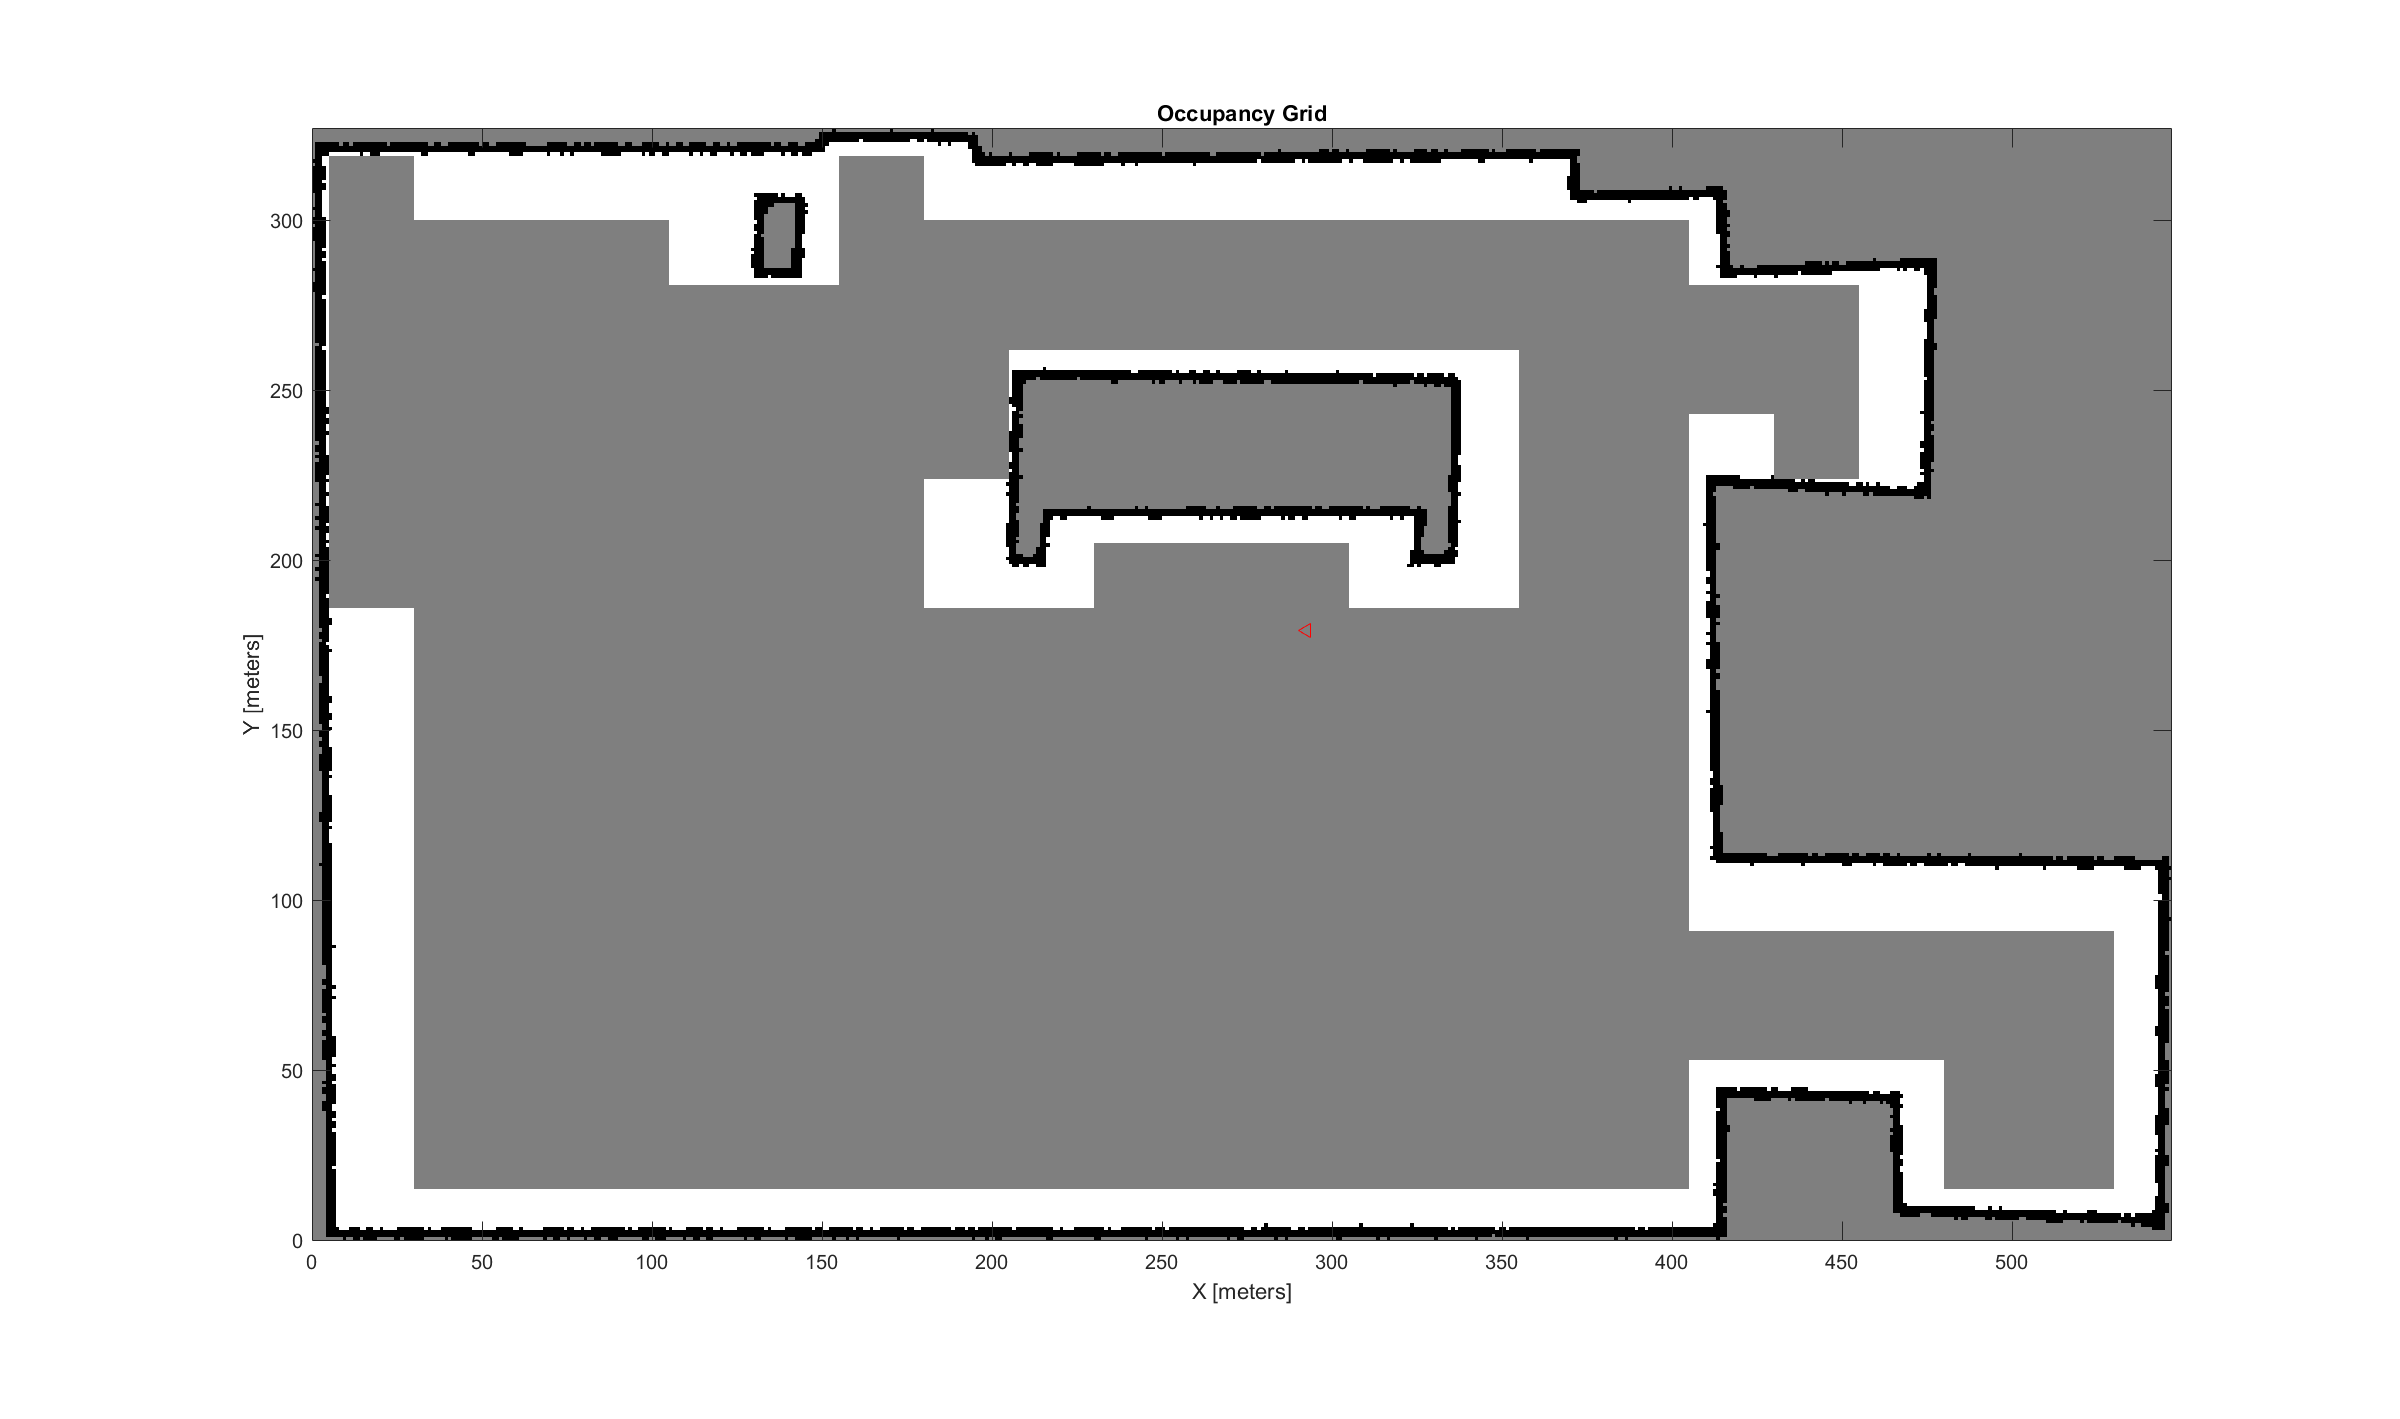

pc =     34    18


pc =     53    18


pc =     72    18


pc =     91    18


pc =    110    18


pc =    129    18


pc =    129    43


pc =    148    43


pc =    167    43


pc =    186    43


pc =    205    43


pc =    224    43


pc =    243    43


pc =    262    43


pc =    281    43


pc =    300    43


pc =    300    68


pc =    281    68


pc =    262    68


pc =    243    68


pc =    224    68


pc =    205    68


pc =    186    68


pc =    167    68


pc =    148    68


pc =    129    68


pc =    110    68


pc =    110    43


pc =     91    43


pc =     72    43


pc =     53    43


pc =     34    43


pc =     34    68


pc =     53    68


pc =     72    68


pc =     91    68


pc =     91    93


pc =    110    93


pc =    129    93


pc =    148    93


pc =    167    93


pc =    186    93


pc =    205    93


pc =    224    93


pc =    243    93


pc =    262    93


pc =    281    93


pc =    300    93


pc =    300   118


pc =    281   118


pc = 1×2
   262   118


pc = 1×2
   243   118


pc = 1×2
   224   118


pc = 1×2
   205   118


pc = 1×2
   186   118


pc = 1×2
   167   118


pc = 1×2
   148   118


pc = 1×2
   129   118


pc = 1×2
   110   118


pc = 1×2
    91   118


pc = 1×2
    72   118


pc = 1×2
    72    93


pc = 1×2
    53    93


pc = 1×2
    34    93


pc = 1×2
    53   118


pc = 1×2
    53   143


pc = 1×2
    72   143


pc = 1×2
    91   143


pc = 1×2
   110   143


pc = 1×2
   129   143


pc = 1×2
   148   143


pc = 1×2
   167   143


pc = 1×2
   186   143


pc = 1×2
   205   143


pc = 1×2
   224   143


pc = 1×2
   243   143


pc = 1×2
   262   143


pc = 1×2
   281   143


pc = 1×2
   300   143


pc = 1×2
   300   168


pc = 1×2
   281   168


pc = 1×2
   262   168


pc = 1×2
   243   168


pc = 1×2
   224   168


pc = 1×2
   205   168


pc = 1×2
   186   168


pc = 1×2
   167   168


pc = 1×2
   148   168


pc = 1×2
   129   168


pc = 1×2
   110   168


pc = 1×2
    91   168


pc = 1×2
    72   168


pc = 1×2
    53   168


pc = 1×2
    34   168


pc = 1×2
    15   168


pc = 1×2
    34   193


pc = 1×2
    53   193


pc = 1×2
    72   193


pc = 1×2
    91   193


pc = 1×2
   110   168


pc = 1×2
   129   168


pc = 1×2
   148   193


pc = 1×2
   167   193


pc = 1×2
   186   193


pc = 1×2
   205   193


pc = 1×2
   224   193


pc = 1×2
   243   193


pc = 1×2
   262   193


pc = 1×2
   281   193


pc = 1×2
   300   193


pc = 1×2
   300   218


pc = 1×2
   281   218


pc = 1×2
   262   218


pc = 1×2
   243   218


pc = 1×2
   224   218


pc = 1×2
   205   218


pc = 1×2
   186   218


pc = 1×2
   167   218


pc = 1×2
   148   218


pc = 1×2
   148   243


pc = 1×2
   167   243


pc = 1×2
   186   243


pc = 1×2
   205   243


pc = 1×2
   224   243


pc = 1×2
   243   243


pc = 1×2
   262   243


pc = 1×2
   281   243


pc = 1×2
   300   243


pc = 1×2
   300   268


pc = 1×2
   281   268


pc = 1×2
   262   268


pc = 1×2
   243   268


pc = 1×2
   224   268


pc = 1×2
   205   268


pc = 1×2
   186   268


pc = 1×2
   167   268


pc = 1×2
   148   268


pc = 1×2
   129   268


pc = 1×2
   129   243


pc = 1×2
   148   268


pc = 1×2
   148   293


pc = 1×2
   167   293


pc = 1×2
   186   293


pc = 1×2
   205   293


pc = 1×2
   224   293


pc = 1×2
   243   293


pc = 1×2
   262   293


pc = 1×2
   281   293


pc = 1×2
   300   293


pc = 1×2
   300   318


pc = 1×2
   281   318


pc = 1×2
   262   318


pc = 1×2
   243   318


pc = 1×2
   224   318


pc = 1×2
   205   318


pc = 1×2
   186   318


pc = 1×2
   167   318


pc = 1×2
   148   318


pc = 1×2
   148   343


pc = 1×2
   167   343


pc = 1×2
   186   343


pc = 1×2
   205   343


pc = 1×2
   224   343


pc = 1×2
   243   343


pc = 1×2
   262   343


pc = 1×2
   281   343


pc = 1×2
   300   343


pc = 1×2
   300   368


pc = 1×2
   281   368


pc = 1×2
   262   368


pc = 1×2
   243   368


pc = 1×2
   224   368


pc = 1×2
   205   368


pc = 1×2
   186   368


pc = 1×2
   167   368


pc = 1×2
   148   368


pc = 1×2
   129   368


pc = 1×2
   110   368


pc = 1×2
    91   368


pc = 1×2
    72   368


pc = 1×2
    53   368


pc = 1×2
    53   343


pc = 1×2
    53   318


pc = 1×2
    53   293


pc = 1×2
    53   268


pc = 1×2
    53   243


pc = 1×2
    53   218


pc = 1×2
    34   218


pc = 1×2
    34   243


pc = 1×2
    34   268


pc = 1×2
    34   293


pc = 1×2
    34   318


pc = 1×2
    34   343


pc = 1×2
    34   368


pc = 1×2
    34   393


pc = 1×2
    53   393


pc = 1×2
    72   393


pc = 1×2
    91   393


pc = 1×2
   110   393


pc = 1×2
   129   393


pc = 1×2
   148   393


pc = 1×2
   167   393


pc = 1×2
   186   393


pc = 1×2
   205   393


pc = 1×2
   224   393


pc = 1×2
   243   393


pc = 1×2
   262   393


pc = 1×2
   281   393


pc = 1×2
   300   393


pc = 1×2
   300   368


pc = 1×2
   300   343


pc = 1×2
   281   368


pc = 1×2
   300   393


pc = 1×2
   300   368


pc = 1×2
   281   368


pc = 1×2
   281   343


pc = 1×2
   300   368


pc = 1×2
   300   343


pc = 1×2
   300   318


pc = 1×2
   300   293


pc = 1×2
   281   318


pc = 1×2
   281   343


pc = 1×2
   281   368


pc = 1×2
   300   343


pc = 1×2
   300   368


pc = 1×2
   300   393


pc = 1×2
   281   368


pc = 1×2
   281   393


pc = 1×2
   262   418


pc = 1×2
   243   418


pc = 1×2
   243   443


pc = 1×2
   262   443


pc = 1×2
   262   468


pc = 1×2
   243   468


pc = 1×2
   243   493


pc = 1×2
   262   493


pc = 1×2
   281   493


pc = 1×2
   300   493


pc = 1×2
   300   518


pc = 1×2
   281   518


pc = 1×2
   262   518


pc = 1×2
   243   518


pc = 1×2
   243   493


pc = 1×2
   243   468


pc = 1×2
   262   443


pc = 1×2
   243   418


pc = 1×2
   224   393


pc = 1×2
   205   393


pc = 1×2
   186   393


pc = 1×2
   167   393


pc = 1×2
   148   393


pc = 1×2
   129   393


pc = 1×2
   110   393


pc = 1×2
    91   393


pc = 1×2
    72   418


pc = 1×2
    53   418


pc = 1×2
    53   443


pc = 1×2
    72   443


pc = 1×2
    91   443


pc = 1×2
    72   443


pc = 1×2
    53   418


pc = 1×2
    72   443


pc = 1×2
    91   443


pc = 1×2
    72   418


pc = 1×2
    53   443


pc = 1×2
    53   418


pc = 1×2
    53   393


pc = 1×2
    34   368


pc = 1×2
    34   343


pc = 1×2
    34   318


pc = 1×2
    34   293


pc = 1×2
    34   268


pc = 1×2
    34   243


pc = 1×2
    34   218


pc = 1×2
    53   243


pc = 1×2
    53   268


pc = 1×2
    53   293


pc = 1×2
    53   318


pc = 1×2
    53   343


pc = 1×2
    72   368


pc = 1×2
    53   393


pc = 1×2
    72   418


pc = 1×2
    72   443


pc = 1×2
    91   443


pc = 1×2
    72   418


pc = 1×2
    72   393


pc = 1×2
    53   418


pc = 1×2
    53   393


pc = 1×2
    72   418


pc = 1×2
    72   443


pc = 1×2
    53   418


pc = 1×2
    34   393


pc = 1×2
    34   368


pc = 1×2
    53   368


pc = 1×2
    34   393


pc = 1×2
    53   418


pc = 1×2
    72   418


pc = 1×2
    53   393


pc = 1×2
    53   368


pc = 1×2
    34   368


pc = 1×2
    53   393


pc = 1×2
    34   393


pc = 1×2
    53   368


pc = 1×2
    53   393


pc = 1×2
    53   418


pc = 1×2
    53   443


pc = 1×2
    72   443


pc = 1×2
    72   418


pc = 1×2
    91   443


pc = 1×2
    72   443


pc = 1×2
    53   418


pc = 1×2
    72   418


pc = 1×2
    91   393


pc = 1×2
    72   393


pc = 1×2
    72   368


pc = 1×2
    53   343


pc = 1×2
    34   343


pc = 1×2
    53   318


pc = 1×2
    53   343


pc = 1×2
    53   318


pc = 1×2
    34   318


pc = 1×2
    53   293


pc = 1×2
    34   268


pc = 1×2
    34   293


pc = 1×2
    53   268


pc = 1×2
    34   243


pc = 1×2
    53   218


pc = 1×2
    53   243


pc = 1×2
    34   268


pc = 1×2
    53   268


pc = 1×2
    34   243


pc = 1×2
    34   218


pc = 1×2
    53   193


pc = 1×2
    53   218


pc = 1×2
    53   243


pc = 1×2
    53   268


pc = 1×2
    34   268


pc = 1×2
    34   293


pc = 1×2
    34   268


pc = 1×2
    53   268


pc = 1×2
    53   293


pc = 1×2
    53   318


pc = 1×2
    34   318


pc = 1×2
    53   293


pc = 1×2
    34   268


pc = 1×2
    34   243


pc = 1×2
    34   218


pc = 1×2
    53   243


pc = 1×2
    34   243


pc = 1×2
    53   218


pc = 1×2
    72   193


pc = 1×2
    91   193


pc = 1×2
    91   168


pc = 1×2
    72   168


pc = 1×2
    91   143


pc = 1×2
    91   168


pc = 1×2
   110   168


pc = 1×2
   110   143


pc = 1×2
    91   118


pc = 1×2
    72    93


pc = 1×2
    53   118


pc = 1×2
    34    93


pc = 1×2
    53    93


pc = 1×2
    34    93


pc = 1×2
    34    68


pc = 1×2
    34    43


pc = 1×2
    34    68


pc = 1×2
    53    43


pc = 1×2
    34    68


pc = 1×2
    53    68


pc = 1×2
    53    43


pc = 1×2
    34    43


pc = 1×2
    34    68


pc = 1×2
    53    93


pc = 1×2
    34    68


pc = 1×2
    53    68


pc = 1×2
    53    43


pc = 1×2
    34    43


pc = 1×2
    34    68


pc = 1×2
    34    93


pc = 1×2
    53   118


pc = 1×2
    72   118


pc = 1×2
    91   118


pc = 1×2
    72   143


pc = 1×2
    53   143


pc = 1×2
    72   168


pc = 1×2
    53   193


pc = 1×2
    72   193


pc = 1×2
    53   168


pc = 1×2
    34   193


pc = 1×2
    53   168


pc = 1×2
    53   143


pc = 1×2
    53   118


pc = 1×2
    53   143


pc = 1×2
    34   168


pc = 1×2
    15   168


pc = 1×2
    34   168


pc = 1×2
    34   193


pc = 1×2
    53   168


pc = 1×2
    34   193


pc = 1×2
    15   168


pc = 1×2
    34   168


pc = 1×2
    53   193


pc = 1×2
    34   168


pc = 1×2
    53   143


pc = 1×2
    53   168


pc = 1×2
    72   193


pc = 1×2
    91   193


pc = 1×2
    72   168


pc = 1×2
    53   193


pc = 1×2
    53   168


pc = 1×2
    72   168


pc = 1×2
    91   193


pc = 1×2
   110   168


pc = 1×2
    91   143


pc = 1×2
   110   168


pc = 1×2
   129   168


pc = 1×2
   129   143


pc = 1×2
   129   168


pc = 1×2
   148   143


pc = 1×2
   129   143


pc = 1×2
   110   143


pc = 1×2
   110   168


pc = 1×2
   129   168


pc = 1×2
   148   143


pc = 1×2
   148   168


pc = 1×2
   129   143


pc = 1×2
   148   168


pc = 1×2
   148   193


pc = 1×2
   129   168


pc = 1×2
   148   143


pc = 1×2
   167   143


pc = 1×2
   167   168


pc = 1×2
   148   168


pc = 1×2
   167   193


pc = 1×2
   148   193


pc = 1×2
   129   168


pc = 1×2
   129   143


pc = 1×2
   129   118


pc = 1×2
   148   118


pc = 1×2
   167   118


pc = 1×2
   167   143


pc = 1×2
   148   168


pc = 1×2
   129   168


pc = 1×2
   129   143


pc = 1×2
   110   143


pc = 1×2
    91   118


pc = 1×2
   110   118


pc = 1×2
   110    93


pc = 1×2
   129   118


pc = 1×2
   110   143


pc = 1×2
   110   168


pc = 1×2
    91   168


pc = 1×2
    91   193


pc = 1×2
    72   193


pc = 1×2
    53   193


pc = 1×2
    34   193


pc = 1×2
    34   168


pc = 1×2
    53   168


pc = 1×2
    53   193


pc = 1×2
    34   193


pc = 1×2
    34   218


pc = 1×2
    53   243


pc = 1×2
    34   243


pc = 1×2
    34   268


pc = 1×2
    34   293


pc = 1×2
    53   268


pc = 1×2
    53   243


pc = 1×2
    34   243


pc = 1×2
    53   218


pc = 1×2
    72   193


pc = 1×2
    91   168


pc = 1×2
   110   143


pc = 1×2
   129   143


pc = 1×2
   148   118


pc = 1×2
   148    93


pc = 1×2
   129   118


pc = 1×2
   110    93


pc = 1×2
    91    93


pc = 1×2
    72    68


pc = 1×2
    53    68


pc = 1×2
    34    68


pc = 1×2
    53    43


pc = 1×2
    53    68


pc = 1×2
    72    43


pc = 1×2
    72    18


pc = 1×2
    53    18


pc = 1×2
    34    18


pc = 1×2
    53    43


pc = 1×2
    34    18


pc = 1×2
    53    18


pc = 1×2
    34    43


pc = 1×2
    53    18


pc = 1×2
    72    18


pc = 1×2
    53    18


pc = 1×2
    34    43


pc = 1×2
    34    18


pc = 1×2
    34    43


pc = 1×2
    53    68


pc = 1×2
    53    43


pc = 1×2
    34    18


pc = 1×2
    53    18


pc = 1×2
    34    43


pc = 1×2
    53    43


pc = 1×2
    34    68


pc = 1×2
    34    43


pc = 1×2
    34    18


pc = 1×2
    53    43


pc = 1×2
    72    18


pc = 1×2
    91    43


pc = 1×2
   110    43


pc = 1×2
   129    18


pc = 1×2
   110    18


pc = 1×2
    91    18


pc = 1×2
   110    43


pc = 1×2
    91    43


pc = 1×2
   110    68


pc = 1×2
   110    93


pc = 1×2
   110   118


pc = 1×2
    91   143


pc = 1×2
   110   168


pc = 1×2
    91   168


pc = 1×2
    72   168


pc = 1×2
    72   193


pc = 1×2
    53   193


pc = 1×2
    34   168


pc = 1×2
    15   168


pc = 1×2
    34   193


pc = 1×2
    53   218


pc = 1×2
    53   193


pc = 1×2
    72   193


pc = 1×2
    91   168


pc = 1×2
    91   193


pc = 1×2
    72   168


pc = 1×2
    72   193


pc = 1×2
    53   193


pc = 1×2
    53   168


pc = 1×2
    53   143


pc = 1×2
    72   118


pc = 1×2
    91    93


pc = 1×2
    72    93


pc = 1×2
    53   118


pc = 1×2
    72   118


pc = 1×2
    91   118


pc = 1×2
   110   118


pc = 1×2
    91   143


pc = 1×2
    72   168


pc = 1×2
    91   193


pc = 1×2
    72   168


pc = 1×2
    72   143


pc = 1×2
    53   168


pc = 1×2
    34   168


pc = 1×2
    53   193


pc = 1×2
    72   168


pc = 1×2
    53   193


pc = 1×2
    53   168


pc = 1×2
    72   143


pc = 1×2
    72   168


pc = 1×2
    91   143


pc = 1×2
   110   168


pc = 1×2
   110   143


pc = 1×2
   110   118


pc = 1×2
   129    93


pc = 1×2
   129    68


pc = 1×2
   148    68


pc = 1×2
   148    93


pc = 1×2
   167   118


pc = 1×2
   148   143


pc = 1×2
   129   168


pc = 1×2
   148   193


pc = 1×2
   167   168


pc = 1×2
   167   193


pc = 1×2
   148   218


pc = 1×2
   148   243


pc = 1×2
   129   243


pc = 1×2
   148   268


pc = 1×2
   129   293


pc = 1×2
   148   318


pc = 1×2
   148   293


%pc = [15,18];
go = waitforbuttonpress; %CHANGEE!!!
while go == 1 

%Building neural network of map

%find top left corner points in all directions
TL = [pc(1)-6, pc(2)-12];
NW_TL = [pc(1)-25, pc(2)-37];
N_TL = [pc(1)-25, pc(2)-12];
NE_TL = [pc(1)-25, pc(2)+13];
E_TL = [pc(1)-6, pc(2)+13];
SE_TL = [pc(1)+13, pc(2)+13];
S_TL = [pc(1)+13, pc(2)-12];
SW_TL = [pc(1)+13, pc(2)-37];
W_TL = [pc(1)-6, pc(2)-37];

%update status of current grid
for tl_j = TL(2):1:TL(2)+24
    for tl_i = TL(1):1:TL(1)+18
        setOccupancy(map,[tl_i, tl_j],0.5,'grid')
    end 
end 

%map = shadeCells(TL,map);
pause(0.005)
show(map)



%--------------------PATH SELECTION ALGORITHM-------------------------------%
%Heuristic sequence
%left -> bottom -> top -> right -> right bottom -> right top

%Find status of all possible next positions 
%[kNW,n] = directionStatus(NW_TL,map,n);
[kN,n] = directionStatus(N_TL,map,n);
[kNE,n] = directionStatus(NE_TL,map,n);
[kE,n] = directionStatus(E_TL,map,n);
[kSE,n] = directionStatus(SE_TL,map,n);
[kS,n] = directionStatus(S_TL,map,n);
%[kSW,n] = directionStatus(SW_TL,map,n);
[kW,n] = directionStatus(W_TL,map,n);

% modify check the status of all possible next locations
pn =[kW, kS, kN, kE, kSE, kNE]; %don't change order of this array

%check the status of all possible next locations
for value = 1:1:length(pn)
    if pn(value) < 0
        pn(value) = -1; %indicate cell is obstacle
    elseif pn(value) > 0.5
        pn(value) = 1; %indicate cell is uncovered
    elseif (pn(value) > 0) && (pn(value) < 0.5)  
        pn(value) = 0; %indicate cell is covered
    end
end


%modify deadlock event
if sum(pn==1) == 0 %check to for deadlock event
    [kSW,n] = directionStatus(SW_TL,map,n);
    [kNW,n] = directionStatus(NW_TL,map,n);
    search = [kN,kNE,kE,kSE,kS,kSW,kW,kNW]; %search for uncovered location in closest neighbors using neural propagation
    switch max(search)
        case search(1)
            pc = moveNextDirection(N_TL,up_dir,map)
            %disp('north is next')
        case search(2)
            pc = moveNextDirection(NE_TL,up_dir,map)
            %disp('ne is next')
        case search(3)
            pc = moveNextDirection(E_TL,right_dir,map)
            %disp('east is next')
        case search(4)
            pc = moveNextDirection(SE_TL,down_dir,map)
            %disp('se is next')
        case search(5)
            pc = moveNextDirection(S_TL,down_dir,map)
            %disp('south is next')
        case search(6)
            pc = moveNextDirection(SW_TL,down_dir,map)
            %disp('sw is next')
        case search(7)
            pc = moveNextDirection(W_TL,left_dir,map)
            %disp('west is next')
        case search(8)
            pc = moveNextDirection(NW_TL,up_dir,map)
            %disp('nw is next')
    end

     %once uncovered location is found revert back to heuristic path selection
else %continue on with heuristic path selection
    switch max(pn)
        case pn(1)
            pc = moveNextDirection(W_TL,left_dir,map)
            %disp('west is next')
        case pn(2)
            pc = moveNextDirection(S_TL,down_dir,map)
            %disp('south is next')
        case pn(3)
            pc = moveNextDirection(N_TL,up_dir,map)
            %disp('north is next')
        case pn(4)
            pc = moveNextDirection(E_TL,right_dir,map)
            %disp('east is next')
        case pn(5)
            pc = moveNextDirection(SE_TL,down_dir,map)
            %disp('se is next')
        case pn(6)
            pc = moveNextDirection(NE_TL,up_dir,map)
            %disp('ne is next')      
    end
end

%mat = occupancyMatrix(map); %update grid values of the map 
%mesh(n)

% Stop condition 
%check if map/environment is completely covered and end operation 
if sum(n>=0.5, 'all') == 0
    go = 0;
    break
end 

end

function [y,n] = directionStatus(x,map,n_mat)
%Use a try block to iterate through and calcuate n-values for all cells eqauting to the size of bot in specified direction
    try
        n = n_mat;
        for j = x(2):1:x(2)+24 %{Reference; j is cols (goes left to right)}
            for i = x(1)-1:1:x(1)+18  %{Reference; i is rows (goes up and down)}
                %ab = grid2world(map, [i,j]); %current grid position for neural activity calculation
                status = checkOccupancy(map, [i,j], "grid"); %check status of current grid position
                %convert grid values to 'I' values
                if status == 1
                    I = -100; 
                    calculateNeuralActivity
                    return
                end 
            end 
        end 

        %if no cell in the group is an obstacle, check the status of cell where COG is located and use it's n-value for the specified direction
        i = x(1)+6;
        j = x(2)+12;
        %ab = grid2world(map, [i,j]);
        status = checkOccupancy(map, [i,j], "grid");
        switch status
            case -1 %uncovered
                I = 0;
                calculateNeuralActivity
                return
            case 0 %covered 
                I = 100;
                calculateNeuralActivity
                return
        end 
    
    catch %Catch "index out of bounds" errors and assign n-value of specified direction as obstacle (-0.6)
        y = -0.6;
        
    end %for the try/catch

    function calculateNeuralActivity

        I_plus = max([I 0]);
        I_neg = max([-1*I 0]);
        
        %check neural activity level of neighboring neurons, evaluate using ReLu, and calcuate euclidean distance
    
        [North, dNorth] = ReLu(-1,0); %n(i, j-1)
        [South, dSouth] = ReLu(1,0); %n(i+1, j)
        [West, dWest] = ReLu(0,-1); %n(i, j-1)
        [East, dEast] = ReLu(0,1); %n(i, j+1)
        [NW, dNW] = ReLu(-1,-1); %n(i-1, j-1)
        [NE, dNE] = ReLu(-1,+1); %n(i-1, j+1)
        [SW, dSW] = ReLu(1,-1); %n(i+1, j-1)
        [SE, dSE] = ReLu(1,1); %n(i+1, j+1)
        
        
        %store evaluated neural activity values for neighboring neurons (8x1 matrix/array)
        xplus = [North, South, West, East, NW, NE, SW, SE];
        
        %store euclidean distances (1x8 matrix/array)
        wij = [dNorth; dSouth; dWest; dEast; dNW; dNE; dSW; dSE];
        
        %calculate the weight
        weight = xplus * wij; % Matrix operation calculating for the weight (order of operation should not be changed)
        
        %set variables
        A = 80;
        B = 1;
        D = 1;
        %define & evaluate equation using ODE solver 
        eqn = @(t,Xi) ((-A*Xi) + (B-Xi)*(I_plus + weight) - (D+Xi)*I_neg);
        [t,Xi] = ode45(eqn, [0:1], n(i,j));
        n(i,j) = Xi(end);
        y = n(i,j);

    end

    % function to check neural activity level of neighboring neurons, evaluate using ReLu, and calcuate euclidean distance
    function [dir, dir_dist] = ReLu(RowDisp,ColDisp)
        try
            dir = max([n(i + RowDisp, i + ColDisp) 0]); 
            dir_dist = 0.7/((norm(ab - grid2world(map, [i + RowDisp, j + ColDisp]))));
        catch
            dir = 0;
            dir_dist = 0;
        end 
    end 
    
end %for the function


function pc = moveNextDirection(pTL,heading,map)
    pc = [pTL(1)+6, pTL(2)+12];
    gpc = grid2world(map, pc);
    plot(gpc(1), gpc(2),heading)
    %shadeCells(pTL,map)
end 
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% function occ_map = shadeCells(corner,map)
%     for tl_j = corner(2):1:corner(2)+24
%         for tl_i = corner(1):1:corner(1)+18
%             setOccupancy(map,[tl_i, tl_j],0.5,'grid')
%         end 
%     end 
%     occ_map = map;
% end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Check 'status' of cells in size of robot area
%If a cell is flagged as an obstacle, break out of loop and assign cell direction n=-0.6 

%         if status == -1 %uncovered 
%             I = 0;
%         elseif status == 0 %covered 
%             I = 100;
%         else %obstacle
%             I = -100; 
%         end
%        
%         y = n(x(1)+6,x(2)+12);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function [dir, dir_dist] = ReLu(Row,Col,RowDisp,ColDisp,map,n)
%     try
%         dir = max([n(Row + RowDisp, Col + ColDisp) 0]); 
%         dir_dist = 0.7/((norm(ab - grid2world(map, [Row + RowDisp, Col + ColDisp]))));
%     catch
%         dir = 0;
%         dir_dist = 0;
%     end 
% end 
